syms k_p k_i k_d T z E_z U_z K_pa Tao_pa Real
syms s

K_pa = 319.3525;
Tao_pa = 0.0191;


num_sym = K_pa/Tao_pa;
den_sym = s^2 + (1/Tao_pa)*s;

G_s_p = num_sym/den_sym;

%TF de la planta en laplace
[num_P, den_P] = numden(G_s_p);

num_poly_P = sym2poly(num_P);
den_poly_P = sym2poly(den_P);
 
G_s_p_tf = tf(num_poly_P, den_poly_P)


G_s_p_tf =
 
          8.778e17
  ------------------------
  5.25e13 s^2 + 2.749e15 s
 
Continuous-time transfer function.
Model Properties



%TF controlador 
G_s_c_PD = (k_p + (k_d*s))

$$G\_s\_c\_PD = k_{p}+k_{d}\,s$$

----

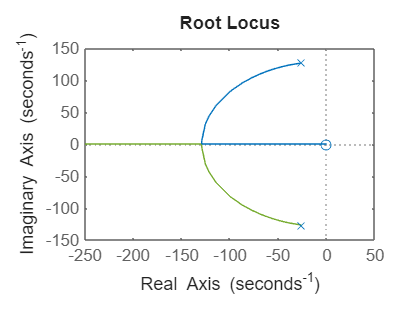

%---------Calculamos la ecuacion de lazo cerrado---------------------

G_s_o = (G_s_p*G_s_c_PD)/(1 + G_s_p*G_s_c_PD);
G_s_o = collect(simplify(G_s_o),s);


%Ecuacion caracteristica co

Ecu_car_PD = (1 + G_s_p*G_s_c_PD);
%con kn constante
k_np = 1;
Ecu_car_PD = subs(Ecu_car_PD,k_p,k_np);
Ecu_car_PD_k_d = solve(Ecu_car_PD, k_d);
Ecu_car_PD_k_d = -1/Ecu_car_PD_k_d;
Ecu_car_PD_k_d = collect(Ecu_car_PD_k_d, s);


%Tf de la ecuacion caracteristica en laplace
[num_PD, den_PD] = numden(Ecu_car_PD_k_d);

% Convertir a polinomios en 's'
num_poly_PD = sym2poly(num_PD);
den_poly_PD = sym2poly(den_PD);

Ecu_Car_PD_k_d_tf = tf(num_poly_PD, den_poly_PD);

figure
hold on
rlocus(Ecu_Car_PD_k_d_tf)

--

% Se aplica la ganancia del integrador

k_nd = 0.01

k_nd = 0.0100

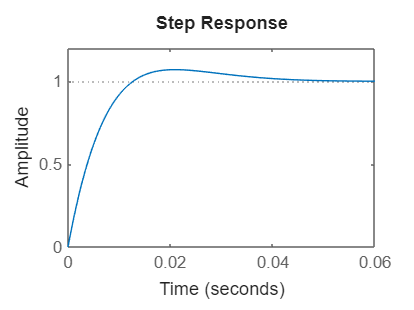

G_s_o = subs(G_s_o,k_d,k_nd);
G_s_o = subs(G_s_o,k_p,k_np);
%Sacar numeradores y denominadores
[num_PD_2, den_PD_2] = numden(G_s_o);

% Convertir a polinomios en 's'
num_poly_PD_2 = sym2poly(num_PD_2);
den_poly_PD = sym2poly(den_PD_2);

G_s_o_tf = tf(num_poly_PD_2, den_poly_PD);


figure
step(G_s_o_tf)


G_s_c_PD = subs(G_s_c_PD,k_d,k_nd);
G_s_c_PD = subs(G_s_c_PD,k_p,k_np);

%Controlador PI en el dominio de laplace

%Sacar numeradores y denominadores
[num_c_PD, den_c_PD] = numden(G_s_c_PD);

% Convertir a polinomios en 's'
num_poly_c_PD = sym2poly(num_c_PD);
den_poly_c_PD = sym2poly(den_c_PD);

G_s_c_tf = tf(num_poly_c_PD, den_poly_c_PD);



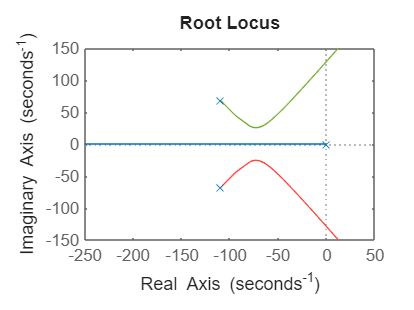

%diseño derivador
G_s_c_PID = G_s_c_PD + k_i/s;



%Ecuacion caracteristica
Ecu_car_PID = (1 + G_s_p*G_s_c_PID);
Ecu_car_PID_k_i = solve(Ecu_car_PID, k_i);
Ecu_car_PID_k_i = -1/Ecu_car_PID_k_i;
Ecu_car_PID_k_i = collect(Ecu_car_PID_k_i, s);


%Tf de la ecuacion caracteristica en con derivador laplace
[num_PID, den_PID] = numden(Ecu_car_PID_k_i);

% Convertir a polinomios en 's'
num_poly_PID = sym2poly(num_PID);
den_poly_PID = sym2poly(den_PID);

Ecu_Car_PID_k_i_tf = tf(num_poly_PID, den_poly_PID);

figure
hold on
rlocus(Ecu_Car_PID_k_i_tf)

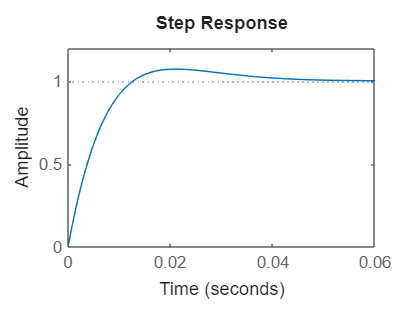

k_ni = 1;
G_s_c_PID = subs(G_s_c_PID,k_i,k_ni);

%Tf de la ecuacion del controlador con derivador en laplace
[num_c_PID, den_c_PID] = numden(G_s_c_PID);

% Convertir a polinomios en 's'
num_poly_PID = sym2poly(num_c_PID);
den_poly_PID = sym2poly(den_c_PID);

G_s_c_PID_tf = tf(num_poly_PID, den_poly_PID);

%Calculo del lazo cerrado con el PID

G_s_o_PID = (G_s_p*G_s_c_PID)/(1 + G_s_p*G_s_c_PID);
G_s_o_PID = collect(simplify(G_s_o_PID),s);


G_s_o_PID = subs(G_s_o_PID,k_i,k_ni);

%Tf de la ecuacion de lazo cerrado con el PID

%Sacar numeradores y denominadores
[num_PID_2, den_PID_2] = numden(G_s_o_PID);

% Convertir a polinomios en 's'
num_poly_PID_2 = sym2poly(num_PID_2);
den_poly_PID_2 = sym2poly(den_PID_2);

G_s_o_PID_tf = tf(num_poly_PID_2, den_poly_PID_2);

figure
step(G_s_o_PID_tf)

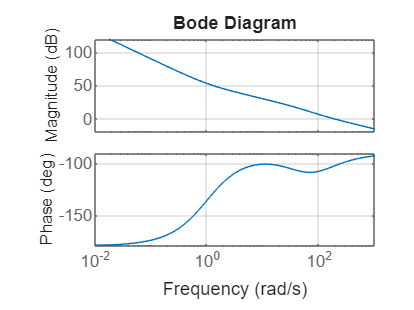


figure
hold on
bode(G_s_p_tf*G_s_c_PID_tf)
grid on